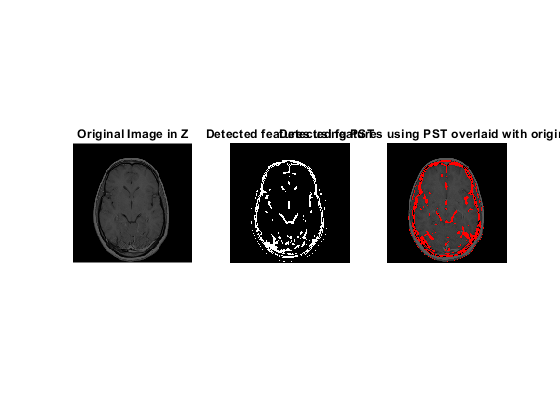

     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



    11



%% Script for PST implementation in 3D Domain
% Author @ Madhuri Suthar, Ph.D. Candidate, Jalali Lab, UCLA
%% Clean Up
clc
clear all
close all
%% 3D Implementation 
load mri
D = squeeze(D);
input=D;
%% PST Implementation
Image_orig=double(input);

% low-pass filtering (also called localization) parameter
handles.LPF=0.21; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

% PST parameters
handles.Phase_strength=0.48;  % PST  kernel Phase Strength
handles.Warp_strength=12.14;  % PST Kernel Warp Strength

% Thresholding parameters (for post processing)
handles.Thresh_min=-1;      % minimum Threshold  (a number between 0 and -1)
handles.Thresh_max=0.0019;  % maximum Threshold  (a number between 0 and 1)

% choose to compute the analog or digital edge
Morph_flag = 1 ; %  Morph_flag=0 to compute analog edge and Morph_flag=1 to compute digital edge.


% define three dimentional cartesian (rectangular) vectors, X, Y and Z
Image_orig_size=size(Image_orig);
L=0.5;
x=linspace(-L,L,Image_orig_size(1));
y=linspace(-L,L,Image_orig_size(2));
z=linspace(-L,L,Image_orig_size(3));

[X,Y,Z]=ndgrid(x,y,z);
% Convert cartesian X, Y and Z vectors to polar vector RHO
RHO = sqrt(X.^2+Y.^2+Z.^2);

% low pass filter the original image to reduce noise
Image_orig_f=fftn(Image_orig);
sigma=(handles.LPF)^2/log(2);
Image_orig_f=Image_orig_f.*fftshift(exp(-(RHO/sqrt(sigma)).^2));
Image_orig_filtered=real(ifftn((Image_orig_f)));

% Construct the PST Kernel
PST_Kernel=(RHO*handles.Warp_strength.*atan(RHO*handles.Warp_strength)-0.5*log(1+(RHO*handles.Warp_strength).^2));
PST_Kernel=PST_Kernel/max(max(max(PST_Kernel)))*handles.Phase_strength;

% Apply the PST Kernel
temp=(fftn(Image_orig_filtered)).*fftshift(exp(-1j*PST_Kernel));
Image_orig_filtered_PST=ifftn(temp);

% Calculate phase of the transformed image
PHI_features=angle(Image_orig_filtered_PST);

if Morph_flag ==0
    out=PHI_features;
else
    % find image sharp transitions by thresholding the phase
    features=zeros(size(PHI_features));
    features(find(PHI_features>handles.Thresh_max))=1;
    features(find(PHI_features<handles.Thresh_min))=1;  % because output phase has both positive and negative values
    features(find(Image_orig<max(max(max(Image_orig)))/20))=0; % ignore the features in the very dark areas of the image
    
%     apply binary morphological operations to clean the transformed image
%     These operations are 2D so the code needs modifications
%     out=features;
%     out = bwmorph(out,'thin',1);
%     out = bwperim(out,4);
%     out = bwmorph(out,'thin',1);
%     out = bwmorph(out,'clean',30);
%     out = bwmorph(out,'remove',5); 
end
%% Show Results
% Show in Z
figure,
for index=1:Image_orig_size(3)
Image_section=reshape(input(:,:,index),Image_orig_size(1),Image_orig_size(2));
subplot(131),imshow(Image_section),title('Original Image in Z')
PST_Features=reshape(features(:,:,index),Image_orig_size(1),Image_orig_size(2));
subplot(132),imshow(PST_Features),title('Detected features using PST')
overlay = double(imoverlay(Image_section, PST_Features/1000000, [1 0 0]));
subplot(133),imshow(overlay/max(max(max(overlay)))),title('Detected features using PST overlaid with original image')
disp(index)
hold on
pause(0.2);
end

% Show in Y
figure,
for index=1:Image_orig_size(2)
Image_section=reshape(input(:,index,:),Image_orig_size(1),Image_orig_size(3));
subplot(131),imshow(Image_section),title('Original Image in Y')
PST_Features=reshape(features(:,index,:),Image_orig_size(1),Image_orig_size(3));
subplot(132),imshow(PST_Features),title('Detected features using PST')
overlay = double(imoverlay(Image_section, PST_Features/1000000, [1 0 0]));
subplot(133),imshow(overlay/max(max(max(overlay)))),title('Detected features using PST overlaid with original image')
disp(index)
hold on
pause(0.2);
end
% Show in X
figure,
for index=1:Image_orig_size(1)
Image_section=reshape(input(index,:,:),Image_orig_size(2),Image_orig_size(3));
subplot(131),imshow(Image_section),title('Original Image in X')
PST_Features=reshape(features(index,:,:),Image_orig_size(2),Image_orig_size(3));
subplot(132),imshow(PST_Features),title('Detected features using PST')
overlay = double(imoverlay(Image_section, PST_Features/1000000, [1 0 0]));
subplot(133),imshow(overlay/max(max(max(overlay)))),title('Detected features using PST overlaid with original image')
disp(index)
hold on
pause(0.2);
end